# Time Series - 2023/1

## Name: Bruno Baptista Guerra

## Deadline: 18-jun-2023

## Setup

clear
clc
I = 4; % put your number here
datetime('now')

ans = datetime
   18-Jun-2023 18:03:35


## Startup

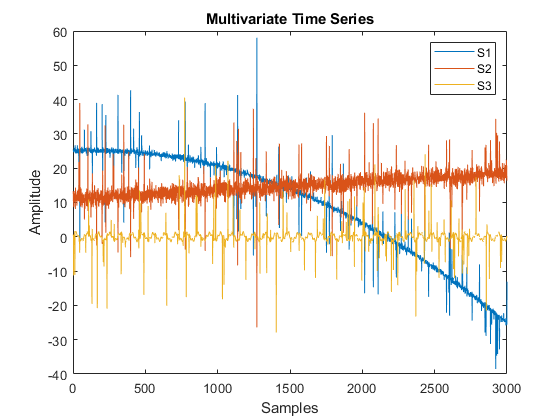

Ts = problems(I);
figure
plot(Ts)
xlabel('Samples')
ylabel('Amplitude')
title('Multivariate Time Series')
legend('S1','S2','S3')

## Activity 1 - Data Processing

The "Ts" matrix contains the raw data from sensors of an industrial process. Use the data to perform the tasks requested in the items below.

**1.1 Make the necessary treatments to fit the multivariate time series data to the regression procedures. Plot the treated time series.**

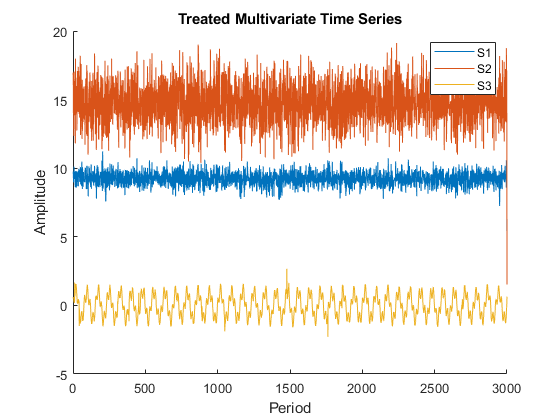

% Data Treatment
t = 1:3000;
S1 = Ts(:,1);
S2 = Ts(:,2);
S3 = Ts(:,3);

%S1 ----------------------------------------
S1_missing = fillmissing(S1,"movmean",10);
S1_detrend = detrend(S1_missing,2,[],"omitnan");
S1_outlier = filloutliers(S1_detrend,"spline");
S1_movmean = filloutliers(S1_outlier,"clip","movmedian",5);
S1_trend = S1_missing - S1_detrend;
S1_final = S1_movmean + mean(S1_trend);
%S2 ----------------------------------------
S2_missing = fillmissing(S2,"pchip");
S2_detrend = detrend(S2_missing,1);
S2_outlier = filloutliers(S2_detrend,"pchip");
S2_trend = S2_missing-S2_detrend;
S2_final = S2_outlier + mean(S2_trend);
%S3 ----------------------------------------
S3_missing = fillmissing(S3,"pchip");
S3_outlier = filloutliers(S3_missing,"pchip");
S3_outlier = filloutliers(S3_outlier,"clip","movmean",5);
S3_final = filloutliers(S3_outlier,"pchip","movmedian",5);

figure;
hold on
plot(t,S1_final);
plot(t,S2_final);
plot(t,S3_final);
xlabel('Period');
ylabel('Amplitude');
title('Treated Multivariate Time Series');
legend('S1','S2', 'S3');
hold off

**1.2 Analyze collinearity (Belsley and Correlation Matrix with ScatterPlot).**

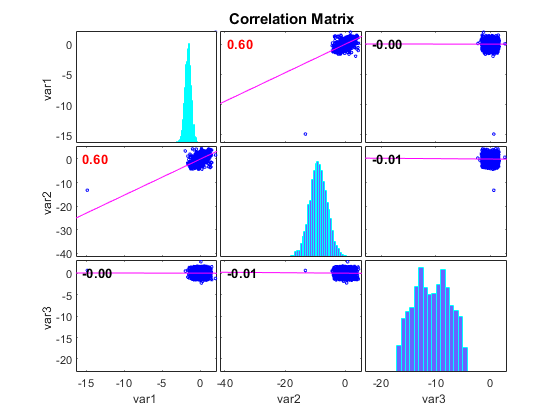

% Collinearity Analysis
Ts_corr = [S1_outlier S2_outlier S3_final];
corrplot(Ts_corr,'testR','on')

    The Correlation Matrix is a standard measure of the strength of pairwise linear relationships between multiple time series. In this Figure, , including the following subplots:

- Each off-diagonal subplot contains a scatterplot of a pair of variables and a least-squares reference line whose slope corresponds to the displayed correlation coefficient;

- Each diagonal subplot contains the distribution of one variable as a histogram.

    The Pearson correlation coefficient (r) is used to measure the strength and direction of the linear relationship between two variables. Mathematically, this can be done by dividing the covariance of the two variables by the product of their standard deviations. The value of r can range from -1 to 1. A correlation of -1 indicates a perfect negative correlation, while a correlation of 1 indicates a perfect positive correlation. A correlation of 0 indicates that there is no association between the movements of the two variables.

    As we can see, the S1 and S2 have moderate positive correlation by the r value of 0.6020, and the scatter plot confirms that analysis. But, it's not the same for S3 when compare with the two other variables, because there are r values really close to 0 (-0.0022 and -0.0091). 

    For the p-value, that computes correlations between all pairs of variables in the input table. For all three variables, the significance level is bigger than 0.05. So, we conclude that the correlation is not statically significant.   

collintest(Ts_corr);


Variance Decomposition

 sValue  condIdx   var1    var2    var3  
-----------------------------------------
 1.2646    1      0.2003  0.2004  0.0001 
 1.0000   1.2647  0.0002  0.0000  0.9997 
 0.6331   1.9976  0.7995  0.7996  0.0002 


    The condition index identifies the number and strength of any close dependencies between variables in the variable matrix. For all variables, reflects a weak dependencies as far as that condition indices in the range below of 5 to 10.

## **Activity 2 - Time Series Decomposition**

Using the raw data, "Ts":

**2.1 Perform the time series decomposition using MODWT. Carry out the necessary treatments. Use 6 levels in decomposition. Show the subseries of each level.**

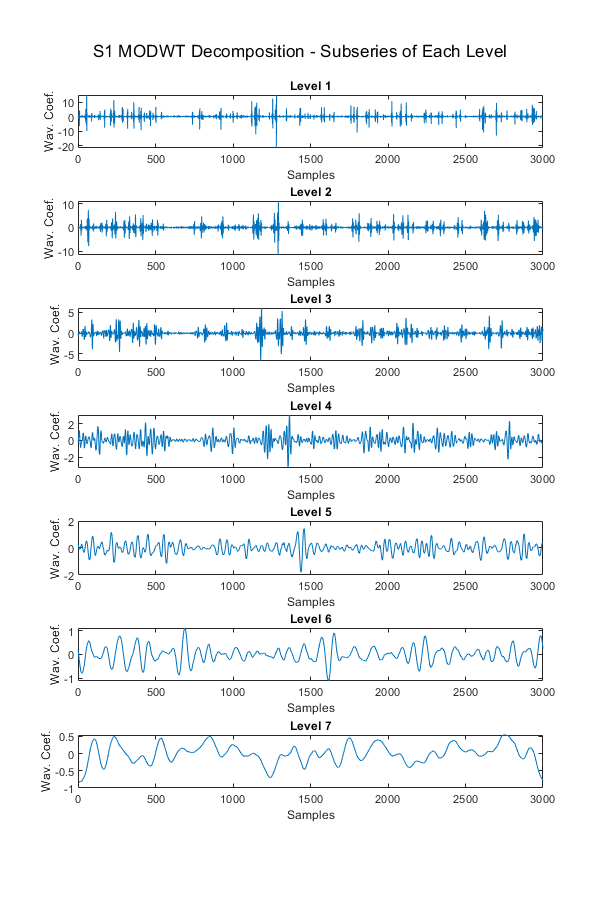

% Pretreatment
% Set the MODWT wavelet and level parameters
wname = 'db6'; % choose a wavelet
num_levels = 6;

% Perform MODWT on the time series
%S1 ----------------------------------------
S1_modwt = modwt(S1_detrend, wname, num_levels);
%S2 ----------------------------------------
S2_modwt = modwt(S2_detrend, wname, num_levels);
%S3 ----------------------------------------
S3_modwt = modwt(S3_missing, wname, num_levels);

% Initialize a figure to display the subseries
f = figure;
f.Position(3:4) = [600 900];
% Plot the subseries for each level
for level = 1:num_levels+1
    subplot(num_levels+1, 1, level);
    plot(t, S1_modwt(level,:));
    xlabel('Samples');
    ylabel('Wav. Coef.');
    title(['Level ' num2str(level)]);
end
% Adjust the figure layout
sgtitle('S1 MODWT Decomposition - Subseries of Each Level');

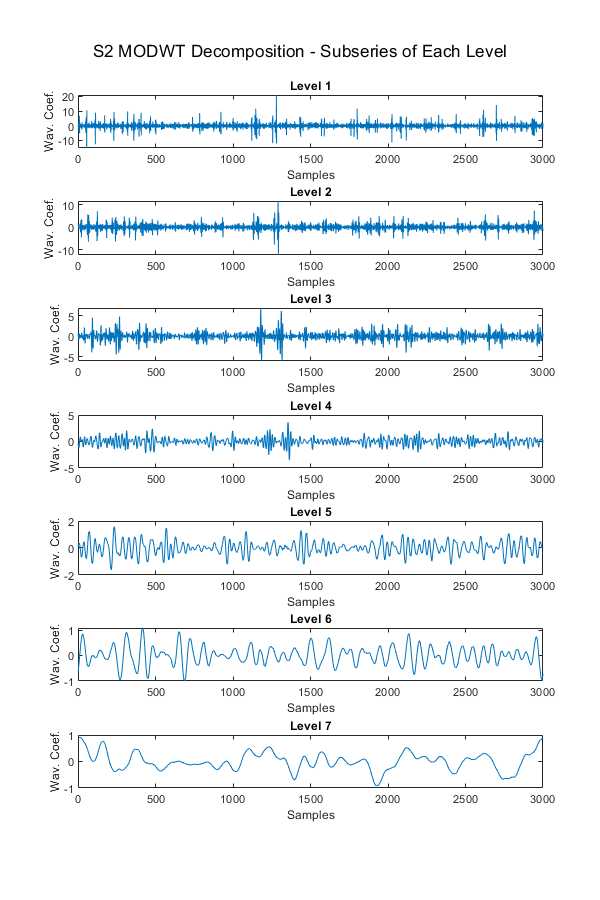

% Initialize a figure to display the subseries
f = figure;
f.Position(3:4) = [600 900];
% Plot the subseries for each level
for level = 1:num_levels+1
    subplot(num_levels+1, 1, level);
    plot(t, S2_modwt(level,:));
    xlabel('Samples');
    ylabel('Wav. Coef.');
    title(['Level ' num2str(level)]);
end
% Adjust the figure layout
sgtitle('S2 MODWT Decomposition - Subseries of Each Level');

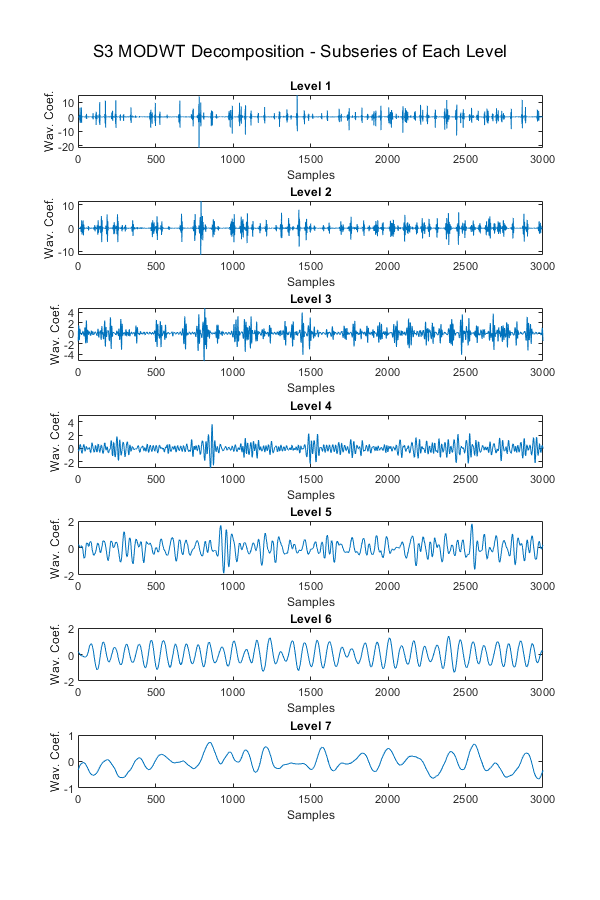

% Initialize a figure to display the subseries
f = figure;
f.Position(3:4) = [600 900];
% Plot the subseries for each level
for level = 1:num_levels+1
    subplot(num_levels+1, 1, level);
    plot(t, S3_modwt(level,:));
    xlabel('Samples');
    ylabel('Wav. Coef.');
    title(['Level ' num2str(level)]);
end
% Adjust the figure layout
sgtitle('S3 MODWT Decomposition - Subseries of Each Level');

**2.2 Make the necessary treatments to fit the multivariate time series data to the regression procedures. Plot the treated time series.**

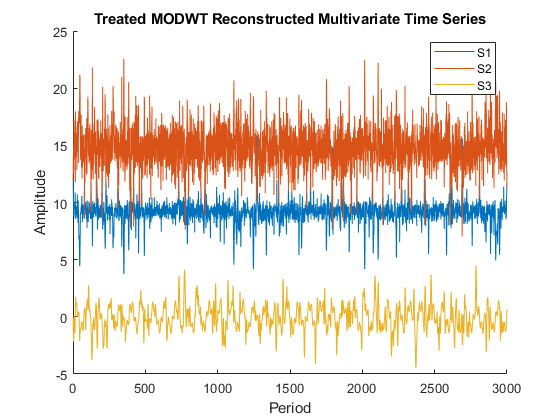

% Data Treatment
for i = 1:num_levels+1
    S1_modwt_outlier(i,:) = filloutliers(S1_modwt(i,:),"spline");
    S1_modwt_final(i,:) = filloutliers(S1_modwt_outlier(i,:),"clip","movmedian",5);
end
for i = 1:num_levels+1
    S2_modwt_outlier(i,:) = filloutliers(S2_modwt(i,:),"pchip");
end
for i = 1:num_levels+1
    S3_modwt_outlier(i,:) = filloutliers(S3_modwt(i,:),"pchip");
    S3_modwt_movmean(i,:) = filloutliers(S3_modwt_outlier(i,:),"clip","movmedian",5);
end

% Perform the IMODWT reconstruction
%S1 ----------------------------------------
S1_reconstructed = imodwt(S1_modwt_final,wname);
S1_reconstructed = S1_reconstructed + mean(S1_trend);
%S2 ----------------------------------------
S2_reconstructed = imodwt(S2_modwt_outlier,wname);
S2_reconstructed = S2_reconstructed + mean(S2_trend);
%S3 ----------------------------------------
S3_reconstructed = imodwt(S3_modwt_movmean,wname);

% Plot the reconstructed time series
figure;
hold on
plot(t, S1_reconstructed);
plot(t, S2_reconstructed);
plot(t, S3_reconstructed);
xlabel('Period');
ylabel('Amplitude');
title('Treated MODWT Reconstructed Multivariate Time Series');
legend('S1','S2', 'S3');
hold off

**2.3 Analyze collinearity (Belsley and Correlation Matrix with ScatterPlot).**

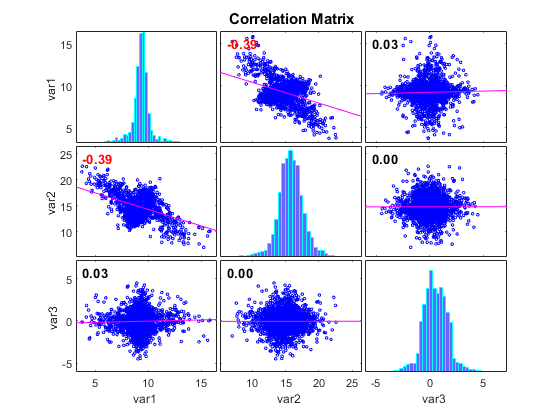

R =     1.0000   -0.3945    0.0294
   -0.3945    1.0000    0.0010
    0.0294    0.0010    1.0000


PValue =     1.0000    0.0000    0.1079
    0.0000    1.0000    0.9573
    0.1079    0.9573    1.0000


% Collinearity Analysis
S1_reconstructed = transpose(S1_reconstructed);
S2_reconstructed = transpose(S2_reconstructed);
S3_reconstructed = transpose(S3_reconstructed);

Ts_corr_modwt = [S1_reconstructed S2_reconstructed S3_reconstructed];
[R,PValue] = corrplot(Ts_corr_modwt,'testR','on')

    The results obtained were similar to item 1.3. In the same way, S1 and S2 have moderate positive correlation by the r value of -0.3945, and the scatter plot confirms that analysis. But, it's not the same for S3 when compare with the two other variables, because there are r values really close to 0 (0.0294 and 0.0010).

    In the Belsley's collinearity test, it did not reach indexes above 30, indicating low dependence. In this way, the variables do not have dependencies on each other.

[sValue,condIdx,VarDecomp] = collintest(Ts_corr_modwt);


Variance Decomposition

 sValue  condIdx   var1    var2    var3  
-----------------------------------------
 1.4079    1      0.0102  0.0102  0.0014 
 0.9987   1.4098  0.0001  0.0000  0.9983 
 0.1428   9.8586  0.9898  0.9898  0.0003 


**2.4 Compare the PDF (Probability Density Functions) from the original time series and those covered in Activity 1 and here in Activity 2.**

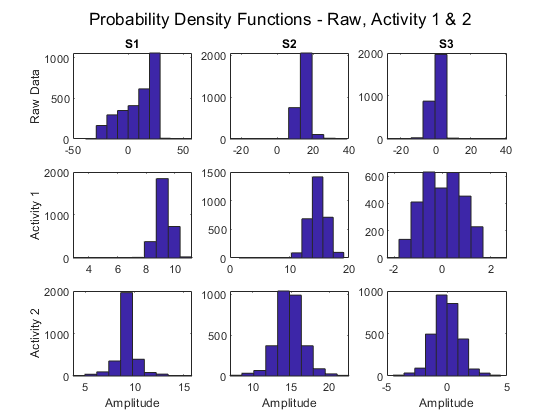

% Comparison PDF
figure
subplot(3,3,1)
hist(S1)
ylabel('Raw Data')
title('S1')
subplot(3,3,2)
hist(S2)
title('S2')
subplot(3,3,3)
hist(S3)
title('S3')
subplot(3,3,4)
hist(S1_final)
ylabel('Activity 1')
subplot(3,3,5)
hist(S2_final)
subplot(3,3,6)
hist(S3_final)
subplot(3,3,7)
hist(S1_reconstructed)
ylabel('Activity 2')
xlabel('Amplitude')
subplot(3,3,8)
hist(S2_reconstructed)
xlabel('Amplitude')
subplot(3,3,9)
hist(S3_reconstructed)
xlabel('Amplitude')
sgtitle('Probability Density Functions - Raw, Activity 1 & 2');

    When we verify the histograms in the PDF (Probability Density Functions), we see that the magnitude of the series (with due treatments and trend removal) obtained in Activity 2 are greater, with emphasis on series S1. In this way, the series found in Activity 1 are more adequate to carry out the regression, because as the magnitude is smaller, the regression residual tends to be smaller.

**2.5 Compare the collinearity tests covered in Activity 1 and here in Activity 2.**

Comparing the results in the collinearity tests covered in Activity 1 and here in Activity 2, in both cases the results are relativates the sames. The principal difference was inverse of R-value between S1 and S2 that goes from 0.6020 to -0.3945 in activity 2. For S3 in the two acitivities are close to 0.

## **Activity 3 - Neural Network Forecasting**

Using the time series S3 from the Activity 1 or 2 (use the best), perform the following tasks:

**3.1 Use a NAR regression to forecast a 5-sample horizon of the time series. Plot the original, trained, and predicted series on the same graph.**

S3_act3 = transpose(S3_final);
% NAR
HP = 5;
Delay = 15;
net = treinaRNAX(S3_act3,[],(HP):HP+Delay,[],10,0); % treina para remoção de 5 amostras

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
 
Computing Resources:
Parallel Workers:
  Worker 1 on Bruno, MEX on PCWIN64
  Worker 2 on Bruno, MEX on PCWIN64
  Worker 3 on Bruno, MEX on PCWIN64
  Worker 4 on Bruno, MEX on PCWIN64
  Worker 5 on Bruno, MEX on PCWIN64
  Worker 6 on Bruno, MEX on PCWIN64
  Worker 7 on Bruno, MEX on PCWIN64
  Worker 8 on Bruno, MEX on PCWIN64
  Worker 9 on Bruno, MEX on PCWIN64
  Worker 10 on Bruno, MEX on PCWIN64
  Worker 11 on Bruno, MEX on PCWIN64
  Worker 12 on Bruno, MEX on PCWIN64
 


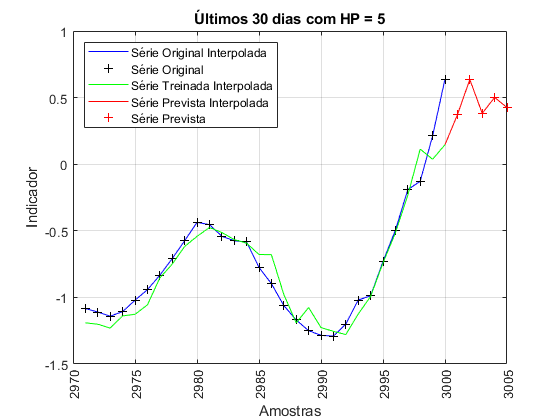

MP = prevRNAX(net,S3_act3,[],HP,'CL');
figure
pprev(MP,S3_act3,HP,1,30,'');

**3.2 Perform a regression analysis and explain the results.**

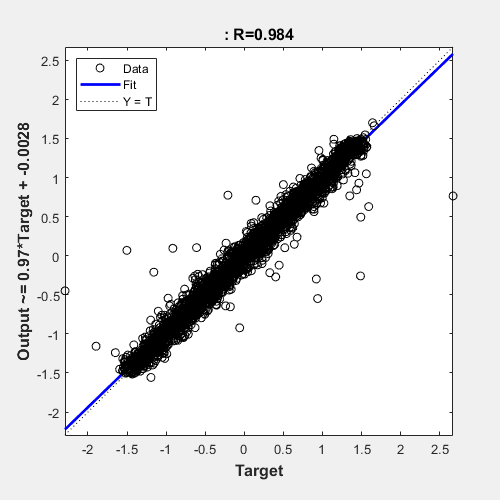

% Regression Analysis
figure
plotregression(S3_act3,MP(1:length(S3_act3)));

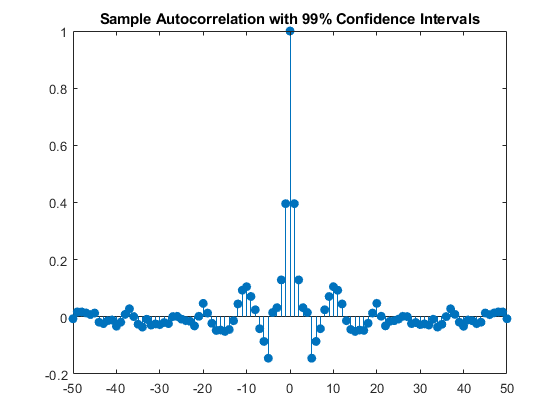

residue = S3_act3 - MP(1:length(S3_act3));
[c, lags] = xcorr(residue,50,'coeff');

figure
stem(lags,c,'filled')
title('Sample Autocorrelation with 99% Confidence Intervals')

    For regression analysis, the first thing we do is plot regression to know the confiable. And then, as we can see the forecast are solid with 0.984, so have a better chance of our regression model fitting the 3000 observations for forecasting a 5-sample horizon of the time series.

    In the second graph, we utilize a cross-correlation to compute and plot the estimated autocorrelation of the residue between S3 and forecast series. The largest spike occurs at zero lag, when residue matches itself exactly.    

**3.3 Calculate the MSE (Mean Squared Error) of the training set and the forecast. Evaluate the results against the time series sample set.**

% MSE
MSE = sum(residue.^2)/length(S3_act3)

MSE = 0.0201

    The MSE value is really short comparing to original series magnitude. In other words, the residuals are small and there ares great quality of predicted values ahead.